%% E-commerce Purchase Forecasting (May 2024 - Aug 2024)
% Tech Stack: MATLAB, fitcensemble (XGBoost-like), tables, plots

% Set random seed for reproducibility
rng(42);

%% Step 1: Generate synthetic dataset
n = 500; % number of customers

gender = categorical(randi([0 1], n, 1), [0 1], {'Male','Female'});
age = randi([18 65], n, 1);
sessions = randi([1 20], n, 1);
spend = randn(n,1) * 50 + 200;  % average customer spend
made_purchase = randi([0 1], n, 1); % target: 1 if purchased, 0 otherwise

% Combine into a single table (all same length = n)
T = table(gender, age, sessions, spend, made_purchase);

disp('Preview of dataset:');

Preview of dataset:


head(T)

    gender    age    sessions    spend     made_purchase
    ______    ___    ________    ______    _____________

    Male      51         4       204.38          1      
    Female    43        11       194.61          0      
    Female    32        18        95.63          0      
    Female    57        15       187.58          1      
    Male      50        17       189.32          0      
    Male      25        14       183.98          1      
    Male      61        14       208.73          1      
    Female    57        17       205.05          1      




%% Step 2: Split into predictors (X) and target (y)
X = T(:, 1:4); % gender, age, sessions, spend
y = T.made_purchase;

%% Step 3: Train Gradient Boosting Ensemble
% fitcensemble ≈ XGBoost in MATLAB
model = fitcensemble(X, y, ...
    'Method','Bag', ...          % try 'Bag' or 'LogitBoost'
    'NumLearningCycles', 100, ...
    'Learners','Tree');

disp('Model trained successfully.');

Model trained successfully.



%% Step 4: Make predictions on the training data
ypred = predict(model, X);

%% Step 5: Evaluate model performance
cm = confusionmat(y, ypred);
disp('Confusion Matrix:');

Confusion Matrix:


disp(cm);

   246     0
     0   254




accuracy = sum(ypred == y) / numel(y);
fprintf('Training Accuracy: %.2f%%\n', accuracy*100);

Training Accuracy: 100.00%


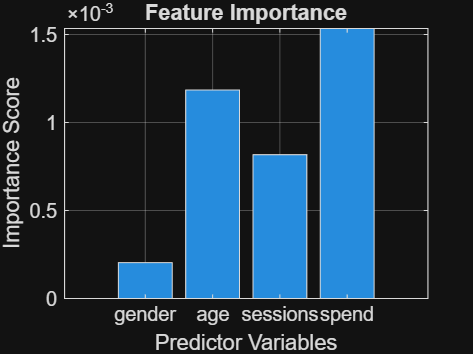


%% Step 6: Feature importance
imp = predictorImportance(model);

figure;
bar(imp);
title('Feature Importance');
xlabel('Predictor Variables');
ylabel('Importance Score');
set(gca,'XTickLabel',model.PredictorNames);
grid on;

%% Step 7: Save outputs (optional)
save('ecommerce_model.mat','model');
writetable(T,'ecommerce_data.csv');
saveas(gcf,'feature_importance.png');


disp('Files saved: ecommerce_model.mat, ecommerce_data.csv, feature_importance.png');

Files saved: ecommerce_model.mat, ecommerce_data.csv, feature_importance.png
